#### Clear buffers

clear all; clc;

#### Define dados iniciais do programa (Forma Aleatória)

Gera os dados de forma derecional e aleatória em determinadas classes

dataQtd = 500;                  % Quantidade de dados em cada classe
classesQtd = 4;                 % Quantidade de classes que serão geradas
Xs = [];        Ys = [];
for i = 1:1:classesQtd
    if (mod(i,2) == 0)
        signal = -1;
    else
        signal = 1;
    end
    Xs = [Xs; [rand(dataQtd,1).*randi(5,dataQtd,1)*signal, rand(dataQtd,1).* ...
    randi(6,dataQtd,1).*signal+i*8]-randi(4,dataQtd,1)];
    Ys = [Ys linspace(i,i,dataQtd)];
end
Ys = Ys';

#### Importa os dados iniciais do programa  (rotation gaussian)

Utiliza uma base de dados pré-definida e tenta realizar a classificação da mesma

load("C:\Users\gabri\OneDrive\Área de Trabalho\scholl\AI\8-Evolution\data.mat")
Xs = Data(:,1:2);
Ys = Data(:,3);

#### Mistura os dados 

Organiza as amostras de forma aleatória para evitar treinamentos de uma unica classe

[qtdElement, dim] = size(Xs);

for i=1:1:qtdElement
    valRan       = randi(qtdElement,1,1);
    aux          = Xs(i,:);
    Xs(i,:)      = Xs(valRan,:);
    Xs(valRan,:) = aux;
    
    aux          = Ys(i,:);
    Ys(i,:)      = Ys(valRan,:);
    Ys(valRan,:) = aux;
end

Plota os dados a serem classificados

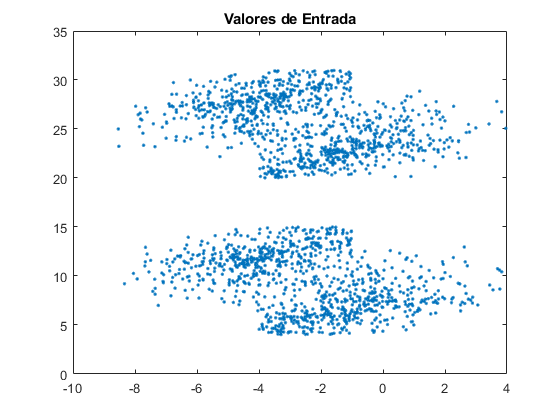

figure(1);  plot(Xs(:,1), Xs(:,2), '.');
title("Valores de Entrada");

#### Define clusters (centros) iniciais

A principio, inicializa-se com dois cluster, sendo um com a posição da primeira

amostra e o segundo na posição (0,0).

error = linspace(0,0,qtdElement); error(1) = 0;
pertinence = linspace(0,0,qtdElement);

clusters = [Xs(1,:) Ys(1) 1; linspace(0,0,dim) 0 0];
pertinence(1) = Ys(1);

#### Inicializa o processo de aprendizagem (online)

for i=2:1:qtdElement
    
    [height width] = size(clusters);    centers = [];
    for j=1:1:height
        centers = [centers; centerCluster(clusters(j,:), dim)];
    end
    
    center = minDistance(Xs(i,:), centers);
    pertinence(i) = clusters(center,dim+1);
    
    if clusters(center,dim+1) == Ys(i)        % Acertou
        clusters(center,:) = upCluster(Xs(i,:), clusters(center,:), dim); 
    else                                      % Errou
        positionC = find(clusters(:, dim+1)==Ys(i),1);
        
        if(isempty(positionC))                % Não encontrou um cluster 
            positionT = find(clusters(:, dim+1)==0, 1);
            
            if(isempty(positionT))                  % Não há nenhum cluster vazio
                clusters = [clusters; [Xs(i,:) Ys(i) 1]];
            else                                    % Há um cluster vazio
                clusters(positionT,:) = [Xs(i,:) Ys(i) 1];
                pertinence(i) = Ys(i);
            end
        else                                    % Encontrou um cluster
            clusters(positionC,:) = upCluster(Xs(i,:), clusters(positionC,:), dim);
        end
    end
end

#### Plota os resultados encontrados de acordo com sua classificação

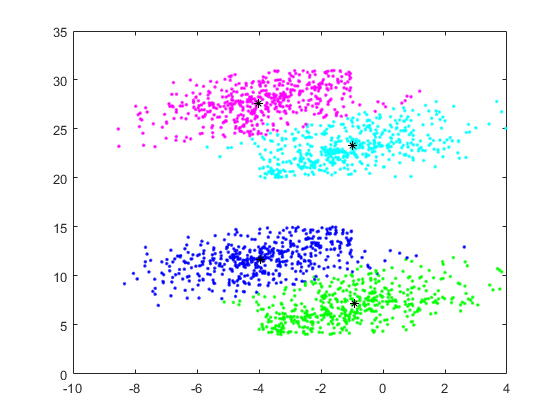

colors = ['r', 'g', 'b', 'c', 'm', 'y', 'w'];
figure(2);
plot(Xs(1,1), Xs(1,2), strcat('.', colors( mod(pertinence(1)+1,6) ))); 

hold on
for i=2:1:qtdElement
    plot(Xs(i,1), Xs(i,2), strcat('.', colors( mod(pertinence(i)+1,6) )));
end
[height width] = size(clusters);    centers = [];
for i=1:1:height
    centers = [centers; centerCluster(clusters(i,:), dim)];
end
plot(centers(:,1), centers(:,2), '*k'); 
hold off;

#### Verifica Acertividade das classificações (Análise)

cont = 0;
for i = 1:1:qtdElement
    if pertinence(i) ~= Ys(i)
        cont = cont + 1;
    end
end
fprintf('Acertos: %d | Erros: %d | Acurácia: %.2f ', qtdElement-cont, ...
    cont, 100*(qtdElement-cont) / qtdElement);

Acertos: 1913 | Erros: 87 | Acurácia: 95.65 

Com dados gerados aleatóriamente o modelo eFMC implementado obteve uma acurácia de 95.85%

em média com um espaço amostral de 15. 

#### Functions

Define a função do calculo da distância 

function idx = minDistance(x, clusters)
    [height, width] = size(clusters);
    distances = linspace(0,0,height);
    for i=1:1:height
        distances(i) = sqrt(sum((clusters(i,:) - x).^2));
    end
    [value, idx] = min(distances);
end

Atualiza informações do cluster com o novo ponto de entrada

function cluster = upCluster(x, cluster, dim)
    cluster(1:dim) = cluster(1:dim) + x;
    cluster(dim+2) = cluster(dim+2) + 1;
end

Retorna o centro do cluster

function center = centerCluster(cluster, dim)
    if(cluster(dim+2) == 0)
        center = cluster(1:dim);
    else
        center = cluster(1:dim) ./ cluster(dim+2);
    end
end